clear;
clc;
close all;

params.mu_r = 1;
params.material = "Copper";

params.geometry.turns = 900; % Number of turns
params.geometry.radius = 0.045; % Radius in meters (45mm)
params.geometry.wirediameter = 0.0003; % Wire diameter in meters (0.3mm)


% Create SolenoidCoil object
secundairyCoil = SolenoidCoil(params);


% Calculate and display self-inductance
Ls = secundairyCoil.calcSelfInductance();
disp(['Self inductance: ', num2str(Ls), ' H']);

Self inductance: 0.021226 H



% Calculate and display resistance
Rs = secundairyCoil.calcResistance(200000);
disp(['Resistance: ', num2str(Rs), ' Ohm']);

Resistance: 62.1933 Ohm



Cs = secundairyCoil.calcParasiticCapacitance();
disp(['Capacitance: ', num2str(Cs), ' Farad']);

Capacitance: 3.0438e-12 Farad


params.mu_r = 1;
params.material = "Copper";

params.geometry.turns = 6; % Number of turns
params.geometry.radius = 0.05; % Radius in meters (5cm)
params.geometry.wirediameter = 0.003; % Wire diameter in meters (3mm)
params.geometry.z_center = -0.15

params = struct with fields:
        mu_r: 1
    material: "Copper"
    geometry: [1×1 struct]



% Create SolenoidCoil object
primaryCoil = SolenoidCoil(params);
 
% Calculate and display self-inductance
Lp = primaryCoil.calcSelfInductance();
disp(['Self inductance: ', num2str(Lp), ' H']);

Self inductance: 5.392e-06 H



% Calculate and display resistance
Rp = primaryCoil.calcResistance(200000);
disp(['Resistance: ', num2str(Rp), ' Ohm']);

Resistance: 0.046069 Ohm



Cp = primaryCoil.calcParasiticCapacitance();
disp(['Capacitance: ', num2str(Cp), ' Farad']);

Capacitance: 2.0292e-13 Farad



M = primaryCoil.MutualInductance(secundairyCoil);
K = primaryCoil.InductiveCouple(secundairyCoil);

disp(['Mutual inductance of transformer: ', num2str(M), ' H']);

Mutual inductance of transformer: 4.765e-05 H


disp(['Inductance couple of transformer: ', num2str(K)]);

Inductance couple of transformer: 0.14085


Delta = Lp*Ls - M^2;

A = [ -Ls*Rp/Delta,   M*Rs/Delta,    M/Delta;
       M*Rp/Delta,   -Lp*Rs/Delta,  -Lp/Delta;
       0,             1/Cs,          0       ];

B = [  Ls/Delta;
      -M/Delta;
       0       ];

Cmat = eye(3);
Dd   = zeros(3,1);

sys = ss(A,B,Cmat,Dd);

% Ingang: 250 kHz sinus, 500 V amplitude
f  = 638e3;
V0 = 330;
u  = @(t) V0*sin(2*pi*f*t);

% Simulatie: meerdere cycli om steady state te pakken
T = 1/f;
t = linspace(0,200*T,20000);  % 200 perioden

u_vec = arrayfun(u,t);
y = lsim(sys,u_vec,t);

% Primaire stroom
ip = y(:,1);

% Neem laatste 50 perioden (steady-state)
idx = t > 150*T;
ip_ss = ip(idx);
t_ss = t(idx);

% RMS berekening
Ip_rms = sqrt(mean(ip_ss.^2));

disp(['Primaire stroom RMS = ', num2str(Ip_rms), ' A']);

Primaire stroom RMS = 29.7854 A



% Max piekwaarde secundaire spanning
disp(['Max vC = ', num2str(max(abs(y(:,3)))/1e3), ' kV']);

Max vC = 309.8936 kV


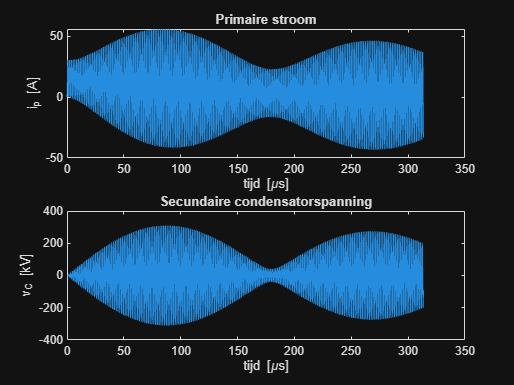

% Plot primaire stroom en secundaire spanning
figure;
subplot(2,1,1);
plot(t*1e6,y(:,1));
xlabel('tijd [\mus]'); ylabel('i_p [A]');
title('Primaire stroom');

subplot(2,1,2);
plot(t*1e6,y(:,3)/1e3);
xlabel('tijd [\mus]'); ylabel('v_C [kV]');
title('Secundaire condensatorspanning');


% === Sweep parameters ===
V0 = 330;                          % excitation amplitude (V peak)
f_range = linspace(1e3,1e6,200);   % from 1 kHz to 1 MHz, 200 points
Vmax = zeros(size(f_range));

for k = 1:length(f_range)
    f = f_range(k);
    u = @(t) V0*sin(2*pi*f*t);

    % Simulate for 200 cycles at frequency f
    T = 1/f;
    t = linspace(0,200*T,4000);
    u_vec = arrayfun(u,t);
    y = lsim(sys,u_vec,t);

    % Take last 50 cycles (steady state)
    idx = t > 150*T;
    vc = y(idx,3);  % capacitor voltage
    Vmax(k) = max(abs(vc));
end

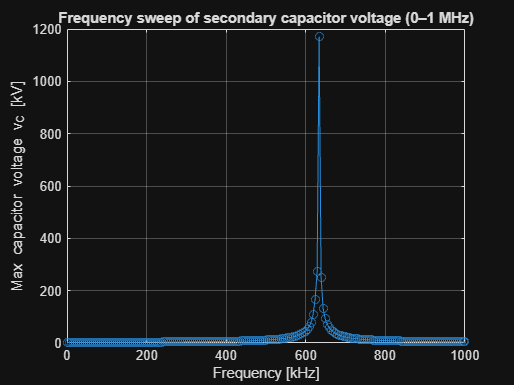



% === Plot result ===
figure;
plot(f_range/1e3, Vmax/1e3,'-o');
xlabel('Frequency [kHz]');
ylabel('Max capacitor voltage v_C [kV]');
title('Frequency sweep of secondary capacitor voltage (0–1 MHz)');
grid on;